clc; close all; clear all;

%% =============================================
%  PARAMETERS
%% =============================================
p.m = 0.1;
p.M = 0.427;
p.l = 0.10382;
p.g = -9.81;

J_true = 8.9432e-4;

%% =============================================
%  BUILD MODEL: No Friction (b = 0)
%% =============================================
alpha = p.m + p.M - (p.m^2 * p.l^2) / (J_true + p.m * p.l^2);
beta  = (J_true + p.m * p.l^2) - (p.m^2 * p.l^2) / (p.m + p.M);

A = [0 1 0 0;
     0, 0, -(p.m^2 * p.l^2 * p.g)/(alpha*(J_true + p.m*p.l^2)), 0;
     0 0 0 1;
     0, 0,  (p.m * p.g * p.l)/beta, 0];

B = [0; 1/alpha; 0; -(p.m*p.l)/beta*(p.m+p.M)];
C = [1 0 0 0; 0 0 1 0];
D = [0; 0];

sys_no_friction = ss(A, B, C, D);

%% =============================================
%  LOAD MEASURED DATA
%% =============================================
data = readmatrix('Control2_ParameterTest.xlsx');

Ts        = data(2,1) - data(1,1);
time_meas = data(1:50, 1);

angle_20 = deg2rad(data(1:50, 3));
angle_50 = deg2rad(data(1:50, 6));
angle_80 = deg2rad(data(1:50, 9));

pwm_vals   = [20, 50, 80];
meas_theta = {angle_20, angle_50, angle_80};
colors     = {'b', 'r', [0.1 0.6 0.1]};

t_meas = time_meas;
Ts_sim = 0.001;
t_sim  = (t_meas(1) : Ts_sim : t_meas(end))';

%% =============================================
%  PARAMETER ESTIMATION (FRICTION b)
%% =============================================
b_guess = 0.1;
options = optimset('Display', 'iter', 'TolX', 1e-4);

best_b = fminsearch(@(b) cost_function(b, p, J_true, t_meas, meas_theta{1}, Ts_sim), ...
                    b_guess, options);

 
 Iteration   Func-count         f(x)         Procedure
     0            1         0.386247         
     1            2         0.386247         initial simplex
     2            4          0.38525         expand
     3            6         0.383635         expand
     4            8         0.382741         reflect
     5           10         0.382665         contract outside
     6           12         0.382665         contract inside
     7           14         0.382657         contract inside
     8           16         0.382657         contract inside
     9           18         0.382657         contract inside
    10           20         0.382657         contract inside
    11           22         0.382657         contract inside
    12           24         0.382657         contract inside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000


fprintf('\nOptimized Friction Coefficient b: %.4f\n', best_b);


Optimized Friction Coefficient b: 0.0423




%% =============================================
%  SIMULATE & PLOT COMPARISON
%% =============================================
fprintf('\n====== RMSE Summary ======\n');


====== RMSE Summary ======


fprintf('%-10s %-20s\n', 'PWM', 'RMSE (b=0)');

PWM        RMSE (b=0)          


fprintf('%s\n', repmat('-', 1, 32));

--------------------------------



% --- PWM 20 (with pi/2 phase shift) ---
N     = length(t_meas);
Y_fft = abs(fft(meas_theta{1}));
Y_fft(1) = 0;
half_N    = floor(N/2);
Y_half    = Y_fft(1:half_N);
f_vec     = (0:half_N-1) / (N * Ts);
[~, idx]  = max(Y_half);
omega_est = 2 * pi * f_vec(idx);

fprintf('PWM %d — Estimated freq: %.4f Hz (%.4f rad/s)\n', ...
        pwm_vals(1), f_vec(idx), omega_est);

PWM 20 — Estimated freq: 0.1200 Hz (0.7540 rad/s)



u_unit      = sin(omega_est * t_sim + pi/2);
y_unit      = lsim(sys_no_friction, u_unit, t_sim);
theta_unit  = interp1(t_sim, y_unit(:,2), t_meas);
scale       = max(abs(meas_theta{1})) / max(abs(theta_unit));
theta_model = scale * theta_unit;

fprintf('PWM %d — scale (b=0): %.4f\n', pwm_vals(1), scale);

PWM 20 — scale (b=0): 5.1084


rmse = rad2deg(sqrt(mean((meas_theta{1} - theta_model).^2)));
fprintf('%-10d %-20.4f\n', pwm_vals(1), rmse);

20         23.7898             



subplot(3,1,1);
plot(t_meas, rad2deg(meas_theta{1}), 'k',  'LineWidth', 2.0, 'DisplayName', 'Measured'); hold on;
plot(t_meas, rad2deg(theta_model),   '--', 'Color', colors{1}, 'LineWidth', 1.5, ...
     'DisplayName', sprintf('Model (b=0), RMSE=%.4f deg', rmse));
title(sprintf('Pendulum Angle \\theta — PWM = %d', pwm_vals(1)));
xlabel('Time (s)'); ylabel('\theta (deg)');
legend('Location', 'best'); grid on;
ylim([-80 80]);

% --- PWM 50 and 80 ---
for i = 2:3
    N     = length(t_meas);
    Y_fft = abs(fft(meas_theta{i}));
    Y_fft(1) = 0;
    half_N    = floor(N/2);
    Y_half    = Y_fft(1:half_N);
    f_vec     = (0:half_N-1) / (N * Ts);
    [~, idx]  = max(Y_half);
    omega_est = 2 * pi * f_vec(idx);

    fprintf('PWM %d — Estimated freq: %.4f Hz (%.4f rad/s)\n', ...
            pwm_vals(i), f_vec(idx), omega_est);

    u_unit      = sin(omega_est * t_sim);
    y_unit      = lsim(sys_no_friction, u_unit, t_sim);
    theta_unit  = interp1(t_sim, y_unit(:,2), t_meas);
    scale       = max(abs(meas_theta{i})) / max(abs(theta_unit));
    theta_model = scale * theta_unit;

    fprintf('PWM %d — scale (b=0): %.4f\n', pwm_vals(i), scale);
    rmse = rad2deg(sqrt(mean((meas_theta{i} - theta_model).^2)));
    fprintf('%-10d %-20.4f\n', pwm_vals(i), rmse);

    subplot(3,1,i);
    plot(t_meas, rad2deg(meas_theta{i}), 'k',  'LineWidth', 2.0, 'DisplayName', 'Measured'); hold on;
    plot(t_meas, rad2deg(theta_model),   '--', 'Color', colors{i}, 'LineWidth', 1.5, ...
         'DisplayName', sprintf('Model (b=0), RMSE=%.4f deg', rmse));
    title(sprintf('Pendulum Angle \\theta — PWM = %d', pwm_vals(i)));
    xlabel('Time (s)'); ylabel('\theta (deg)');
    legend('Location', 'best'); grid on;
    ylim([-80 80]);
end

PWM 50 — Estimated freq: 0.1400 Hz (0.8796 rad/s)


PWM 50 — scale (b=0): 10.5722


50         42.8920             


PWM 80 — Estimated freq: 0.1400 Hz (0.8796 rad/s)


PWM 80 — scale (b=0): 14.7874


80         62.8457             


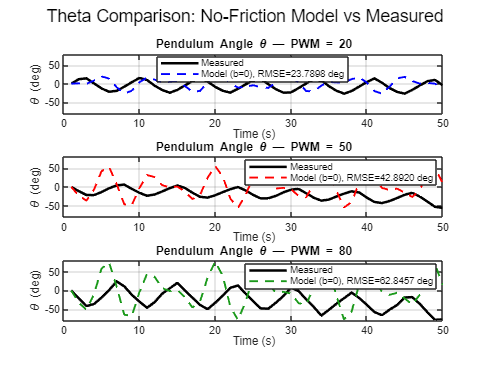


sgtitle('Theta Comparison: No-Friction Model vs Measured');


%% =============================================
%  COST FUNCTION
%% =============================================
function total_error = cost_function(b, p, J_true, t_meas, theta_meas, Ts_sim)
    M_total = p.m + p.M;
    L_p     = J_true + p.m * p.l^2;
    det_val = M_total * L_p - (p.m * p.l)^2;

    A = [0 1 0 0;
         0, -b*L_p/det_val,          -(p.m^2*p.l^2*p.g)/det_val, 0;
         0 0 0 1;
         0,  b*p.m*p.l/det_val,       (p.m*p.g*p.l*M_total)/det_val, 0];

    B = [0; L_p/det_val; 0; -p.m*p.l/det_val];
    C = [1 0 0 0; 0 0 1 0];
    D = [0; 0];

    sys_temp = ss(A, B, C, D);

    t_sim = (t_meas(1) : Ts_sim : t_meas(end))';

    % Estimate frequency from measured data
    N     = length(t_meas);
    Ts    = t_meas(2) - t_meas(1);
    Y_fft = abs(fft(theta_meas));
    Y_fft(1) = 0;
    half_N    = floor(N/2);
    [~, idx]  = max(Y_fft(1:half_N));
    f_vec     = (0:half_N-1) / (N * Ts);
    omega_est = 2 * pi * f_vec(idx);

    u = sin(omega_est * t_sim);
    y = lsim(sys_temp, u, t_sim);

    theta_model = interp1(t_sim, y(:,2), t_meas);
    scale       = max(abs(theta_meas)) / max(abs(theta_model));
    error_vec   = theta_meas - (scale * theta_model);
    total_error = sqrt(mean(error_vec.^2));
end


clc; close all; clear all;
clc; close all; clear all;

%% =============================================
%  PARAMETERS
%% =============================================
p.m = 0.1;
p.M = 0.427;
p.l = 0.10382;
p.g = -9.81;

J_true = 8.9432e-4;

%% =============================================
%  LOAD MEASURED DATA
%% =============================================
data = readmatrix('Control2_ParameterTest.xlsx');

Ts        = data(2,1) - data(1,1);
time_meas = data(1:50, 1);

angle_20 = deg2rad(data(1:50, 3));
angle_50 = deg2rad(data(1:50, 6));
angle_80 = deg2rad(data(1:50, 9));

pwm_vals   = [20, 50, 80];
meas_theta = {angle_20, angle_50, angle_80};
colors     = {'b', 'r', [0.1 0.6 0.1]};

t_meas = time_meas;
Ts_sim = 0.001;
t_sim  = (t_meas(1) : Ts_sim : t_meas(end))';

%% =============================================
%  MULTI-PARAMETER OPTIMIZATION (b, Ku, offset)
%  Optimized using PWM = 20 data
%% =============================================
x0      = [0.1, 1.0, 0.0];
options = optimset('Display', 'iter', 'TolX', 1e-6, 'TolFun', 1e-6, 'MaxIter', 1000);

best_x = fminsearch(@(x) cost_function_multi(x, p, J_true, t_meas, meas_theta{1}, Ts_sim), ...
                    x0, options);

 
 Iteration   Func-count         f(x)         Procedure
     0            1         0.335197         
     1            4         0.335197         initial simplex
     2            6         0.324624         expand
     3            7         0.324624         reflect
     4            9         0.317622         expand
     5           11         0.301361         expand
     6           13         0.289102         expand
     7           15         0.264957         expand
     8           17         0.239311         expand
     9           19         0.233706         expand
    10           20         0.233706         reflect
    11           22         0.233706         contract inside
    12           24         0.233231         contract inside
    13           26         0.232432         contract inside
    14           28         0.232432         contract inside
    15           30         0.232141         contract inside
    16           32         0.231951         contract inside



best_b      = best_x(1);
best_Ku     = best_x(2);
best_offset = best_x(3);

fprintf('\n====== Optimization Results ======\n');


====== Optimization Results ======


fprintf('Friction b   : %.4f\n', best_b);

Friction b   : 6.3753


fprintf('Scale Ku     : %.4f\n', best_Ku);

Scale Ku     : -11.9173


fprintf('Offset (deg) : %.4f\n', rad2deg(best_offset));

Offset (deg) : -6.1525



%% =============================================
%  BUILD MODEL WITH OPTIMIZED b
%% =============================================
C = [1 0 0 0; 0 0 1 0];
D = [0; 0];

M_total = p.m + p.M;
L_p     = J_true + p.m * p.l^2;
det_val = M_total * L_p - (p.m * p.l)^2;

A_opt = [0 1 0 0;
         0, -best_b*L_p/det_val,        -(p.m^2*p.l^2*p.g)/det_val, 0;
         0 0 0 1;
         0,  best_b*p.m*p.l/det_val,     (p.m*p.g*p.l*M_total)/det_val, 0];

B_opt = [0; L_p/det_val; 0; -p.m*p.l/det_val];

sys_opt = ss(A_opt, B_opt, C, D);

%% =============================================
%  SIMULATE & PLOT WITH OPTIMIZED PARAMETERS
%% =============================================
fprintf('\n====== RMSE Summary ======\n');


====== RMSE Summary ======


fprintf('%-10s %-20s\n', 'PWM', 'RMSE (optimized)');

PWM        RMSE (optimized)    


fprintf('%s\n', repmat('-', 1, 32));

--------------------------------



figure;
for i = 1:3
    N     = length(t_meas);
    Y_fft = abs(fft(meas_theta{i}));
    Y_fft(1) = 0;
    half_N    = floor(N/2);
    f_vec     = (0:half_N-1) / (N * Ts);
    [~, idx]  = max(Y_fft(1:half_N));
    omega_est = 2 * pi * f_vec(idx);

    fprintf('PWM %d — Estimated freq: %.4f Hz (%.4f rad/s)\n', ...
            pwm_vals(i), f_vec(idx), omega_est);

    u           = best_Ku * sin(omega_est * t_sim);
    y           = lsim(sys_opt, u, t_sim);
    theta_model = interp1(t_sim, y(:,2), t_meas);

    meas_corrected = meas_theta{i} - best_offset;
    rmse = rad2deg(sqrt(mean((meas_corrected - theta_model).^2)));

    fprintf('%-10d %-20.4f\n', pwm_vals(i), rmse);

    subplot(3,1,i);
    plot(t_meas, rad2deg(meas_corrected), 'k', 'LineWidth', 2.0, 'DisplayName', 'Measured'); hold on;
    plot(t_meas, rad2deg(theta_model),   '--', 'Color', colors{i}, 'LineWidth', 1.5, ...
         'DisplayName', sprintf('Model (b=%.3f, Ku=%.3f), RMSE=%.4f deg', best_b, best_Ku, rmse));
    title(sprintf('Pendulum Angle \\theta — PWM = %d', pwm_vals(i)));
    xlabel('Time (s)'); ylabel('\theta (deg)');
    legend('Location', 'best'); grid on;
    ylim([-100 100]);
end

PWM 20 — Estimated freq: 0.1200 Hz (0.7540 rad/s)


20         9.6276              


PWM 50 — Estimated freq: 0.1400 Hz (0.8796 rad/s)


50         22.0683             


PWM 80 — Estimated freq: 0.1400 Hz (0.8796 rad/s)


80         33.6453             


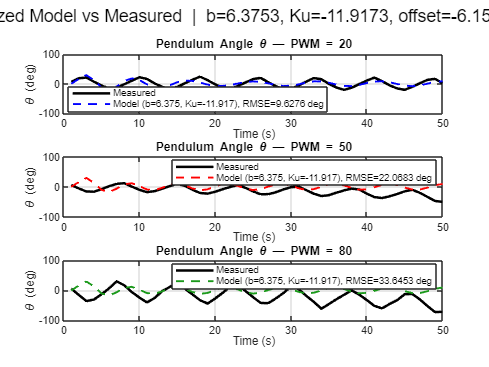


sgtitle(sprintf('Optimized Model vs Measured  |  b=%.4f, Ku=%.4f, offset=%.4f deg', ...
        best_b, best_Ku, rad2deg(best_offset)));


%% =============================================
%  COST FUNCTION
%% =============================================
function total_error = cost_function_multi(x, p, J_true, t_meas, theta_meas, Ts_sim)
    b      = x(1);
    Ku     = x(2);
    offset = x(3);

    M_total = p.m + p.M;
    L_p     = J_true + p.m * p.l^2;
    det_val = M_total * L_p - (p.m * p.l)^2;

    A = [0 1 0 0;
         0, -b*L_p/det_val,        -(p.m^2*p.l^2*p.g)/det_val, 0;
         0 0 0 1;
         0,  b*p.m*p.l/det_val,     (p.m*p.g*p.l*M_total)/det_val, 0];

    B = [0; L_p/det_val; 0; -p.m*p.l/det_val];
    C = [1 0 0 0; 0 0 1 0];
    D = [0; 0];

    sys_temp = ss(A, B, C, D);

    % Estimate frequency from measured data
    Ts    = t_meas(2) - t_meas(1);
    N     = length(t_meas);
    Y_fft = abs(fft(theta_meas));
    Y_fft(1) = 0;
    half_N    = floor(N/2);
    [~, idx]  = max(Y_fft(1:half_N));
    f_vec     = (0:half_N-1) / (N * Ts);
    omega_est = 2 * pi * f_vec(idx);

    t_sim = (t_meas(1) : Ts_sim : t_meas(end))';

    u           = Ku * sin(omega_est * t_sim);
    y           = lsim(sys_temp, u, t_sim);
    theta_model = interp1(t_sim, y(:,2), t_meas);

    error_vec   = (theta_meas - offset) - theta_model;
    total_error = sqrt(mean(error_vec.^2));
end